# EEET-425-2241  Digital Signal Processing Exam 02

## Name:_____Steven Bolt______

## Instructions

#### This exam consists of 4 problems worth 20, 30, 25 and 25 points each.  Complete all the problems in this MATLAB Live Script by entering your code and creating plots as requested or by typing your answers into the space provided.  For problem 1, Convolution you will need to show your work on a separate document (e.g. a spread sheet) or on paper.

#### When you have completed your exam export this MATLAB Live Script to a PDF and submit both files to the Assignments section of myCourses.  Also upload any other files for Problem 1.  If you completed Problem 1 on paper either use a scan application or get a good picture of your exam and convert it to a PDF file.  Use of a scan app is preferred.  If you used an excel spread sheet, submit your spread sheet file.

#### To export your Live Script File to a PDF click the down arrow below the Save Icon and select Export to PDF.    Always double check your exported PDF to see that it is rendered correctly.

#### Be sure to certify your exam by entering your name at the top of this exam file

#### You have approximately 3 hours to complete this exam.  The exam will not automatically close on you, but your time will be monitored.

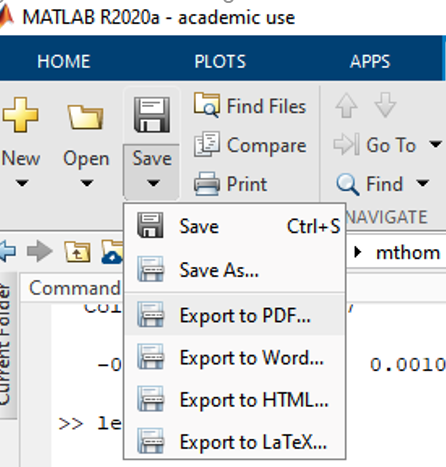

#### Submit all files to the Assignments Section of myCourses.  **DO NOT SUBMIT A ZIP FILE!**

#### I will be on-line during class time.  Use the links in myCourses to the class ZOOM meeting.

## Problem 1 -- Convolution and Linearity (20 points)

#### The system shown below consists of a linear filters that has an impulse response h[n].  The input signals are scaled by different values and summed together then applied to the filter, resulting in the output sequence y[n].  

#### The impulse response of the filter is h[n] = [ -2, 1, 0 , 1].

#### The input x1[n] = [1, -3, 4, 2, -1, 6] and the input x2[n] = [-1, 2, 3, 1, -4, 2].

#### The value of k1 = 2 and the value of k2 = 3

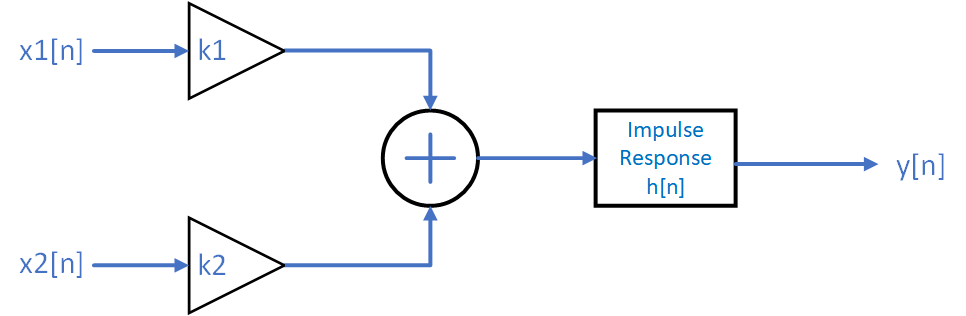

#### A) (5 Pts) What are the two properties that systems must have to be a linear system?  Type your answer below.

Homogeneity and additivity.

#### B) (5 Pts)  What will be the length of the output sequence y[n]?   Type your answer below.

***length = len(input) + len(impulse) - 1 = 6 + 4 - 1 = 9***

#### C) (10 Pts)   Compute the output y[n] of the system of linear filters for the two input sequences x1 and x2.  You do NOT need to use MATLAB to solve this.  You may do this on paper or in a spreadsheet for example. You may NOT use the MATLAB 'conv' function to find the solution though you may use it to check your result.

#### HINT!   Save yourself some time by considering the use of the properties of a linear system to make the computation easier.  Show all your work in computing the output.   You may upload your results scanned from a separate sheet of paper or use an excel spread sheet.

x1 = [1 -3 4 2 -1 6];
k1 = 2;
x1 = x1 * k1

x1 =      2    -6     8     4    -2    12


x2 = [-1, 2, 3, 1, -4, 2];
k2 = 3;
x2 = x2 * k2

x2 =     -3     6     9     3   -12     6


x = x1 + x2

x =     -1     0    17     7   -14    18


h = [-2 1 0 1];
conv(x,h)  % checking my work

ans =      2    -1   -34     2    35   -33    25   -14    18


## Problem 2 --  Windowed SINC FIR Filters (30 points)

#### You are sampling a patient's breathing with a temperature sensor.  You are picking up some unwanted interference on your signal that is a sinewave at a frequency equivalent to 65 BPM.  You can't get rid of it by changing your hardware or moving wires, etc..  You want to get rid of the interference, but you want to retain the signals from 0 BPM to 40 BPM.   You decide to filter the signal to remove the interference as part of the signal processing.

#### A) (5 Pts) What type of filter would you use to remove the interfering tone while retaining the desired signals. lowpass, highpass, bandpass, or bandstop?  Type your answer below.

#### Lowpass with a cutoff at 40 BPM.

#### B) (5 Pts) Load the exam file from myCourses 'Exam_02_2241_Problem_02.mat'.  This file will load a variable 'outData' into the work space.  This variable has two columns each of length 256.  The first column is the sample number and the second column is the signal data.  Create two variables with appropriate names from these columns.  Plot the signal versus the sample number.  Use an appropriate title and x and y axes labels.

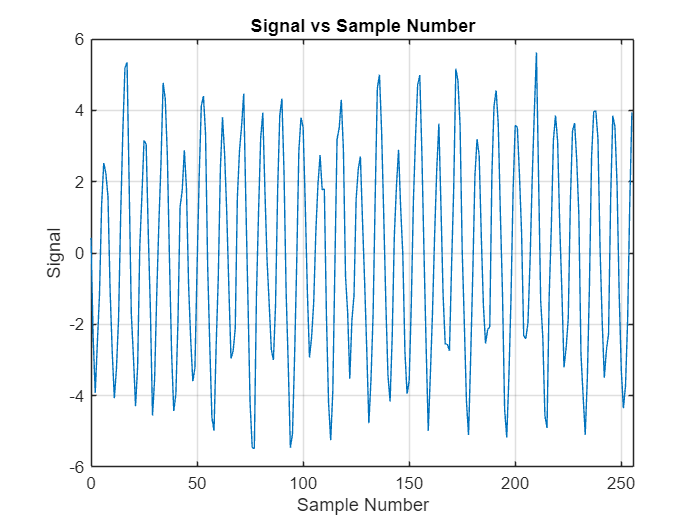

clear
load("Exam_02_2241_Problem_02.mat")

samplenum = outData(:,1);
signal = outData(:,2);

figure
plot(samplenum, signal)
grid 'on'
xlim([0 256])
xlabel("Sample Number")
ylabel("Signal")
title("Input Signal vs Sample Number")

#### C) (5 Pts) Plot the frequency spectrum of the input signal versus the absolute frequency in BPM.  The signal is being sampled at a rate of 600 BPM.  Be sure to create a frequency vector that is in the units of BPM to use for the x-axis.  Display only the frequencies from 0 to the Nyquist frequency.

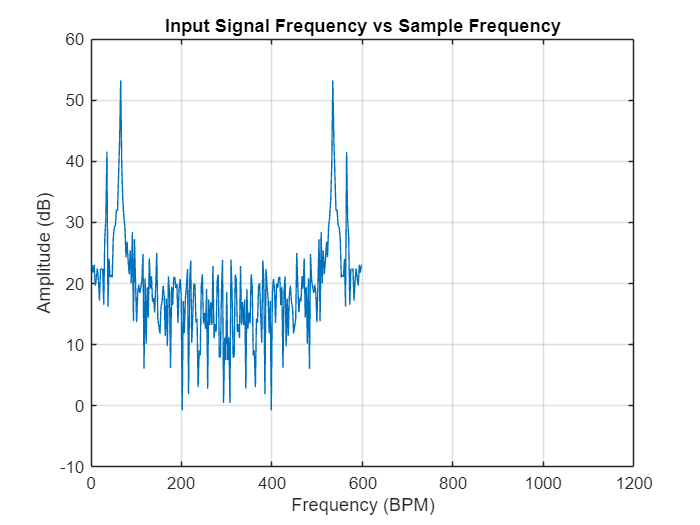

% converting sample numbers to frequency in BPM
N = length(samplenum);  % get number of samples
BPM = (samplenum / N) * 600;  % convert by sample number using 600 BPM

freqResponse = fft(signal);  % find frequency response by taking FFT of signal values
freqResponseMag = 20*log10(abs(freqResponse));  % find the absolute magnitude of the frequency response in dB

% find nyquist freq
sampleRate = 600 / 60;  % convert from BPM to Hz
nyquist = 2 * sampleRate;  % determine nyquist freq
nyquistBPM = nyquist * 60;  % convert from Hz to BPM

figure
plot(BPM, freqResponseMag)
grid 'on'
xlim([0 nyquistBPM])
xlabel("Frequency (BPM)")
ylabel("Amplitude (dB)")
title("Input Signal Frequency vs Sample Frequency")

#### D) (5 Pts) Using the FIR_Designer tool, create an FIR filter to remove the undesired tone at 65 BPM from the desired signals at 40 BPM or less.  Adjust the filter design parameters until the undesired tone is attenuated to at least one-half the magnitude of the desired tone (on a linear scale).  More attenuation is OK.  You may have to do this iteratively. 

#### TIP:  Make sure that the FIR_Designer.m tools is in your working directory so that MATLAB can access it.  Recall the basic syntax for the FIR_Designer tools is:

% h = FIR_Designer('nOrder',11, 'cutBPM',10);

#### where the order and corner frequency are example values (not the correct solution).  Run the function in this Live Script.  This will plot the impulse response and the frequency response in your live script automatically.  Leave these plots in your submission.  It is not necessary to use a fixed point filter for this exercise.


 To print the C Header enable the Fixed Point option

h = [0.009035, 0.028490, 0.085179, 0.161244, 0.216052, 0.216052, 0.161244, 0.085179, 0.028490, 0.009035];


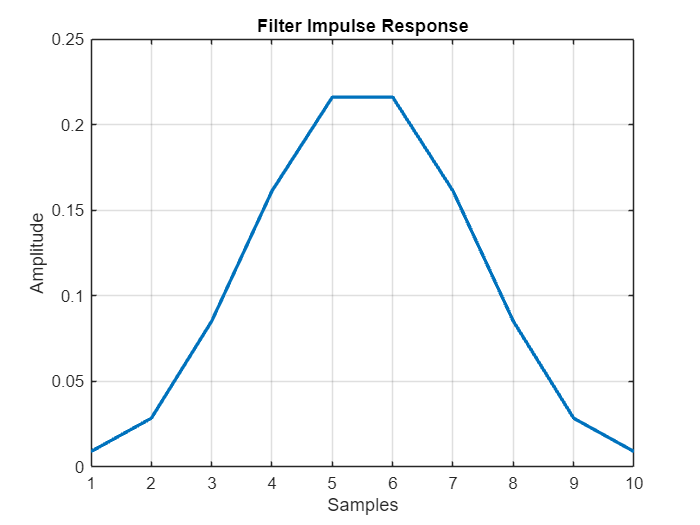

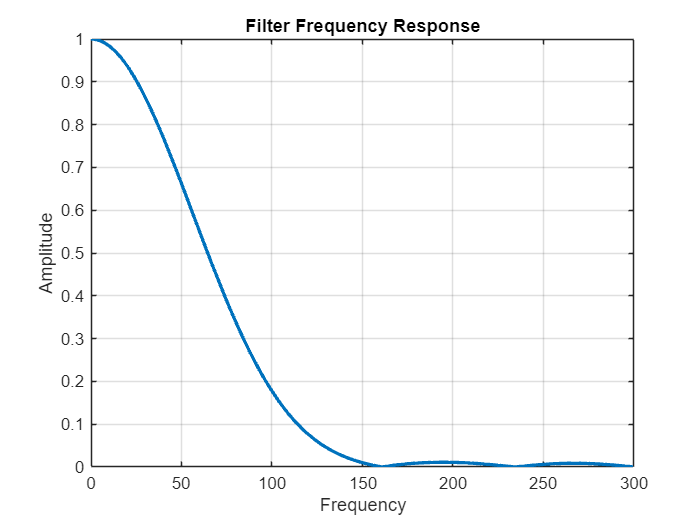

h = FIR_Designer('Type','LPF', 'nOrder',10, 'cutBPM',40);

#### E) (5 Pts) Apply the filter that you designed to the input signal using time domain convolution.  You may use the MATLAB 'conv' function.  Plot the oringinal signal and the resulting time domain signal on the same graph.

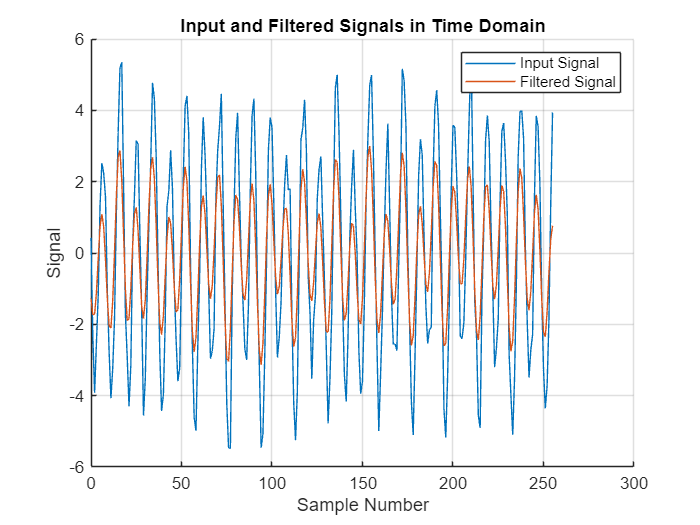

filteredSignal = conv(signal, h, 'same');  % same gives same size output as signal for plotting purposes

figure
hold 'on'
grid 'on'
plot(samplenum, signal)
plot(samplenum, filteredSignal)
hold 'off'
xlabel("Sample Number")
ylabel("Signal")
title("Input and Filtered Signals in Time Domain")
legend("Input Signal", "Filtered Signal")

#### F) (5 Pts)  Plot the resulting frequency spectrum of the output of the filter on a linear scale versus absolute frequency in BPM. Display only the frequencies from 0 to the Nyquist frequency.

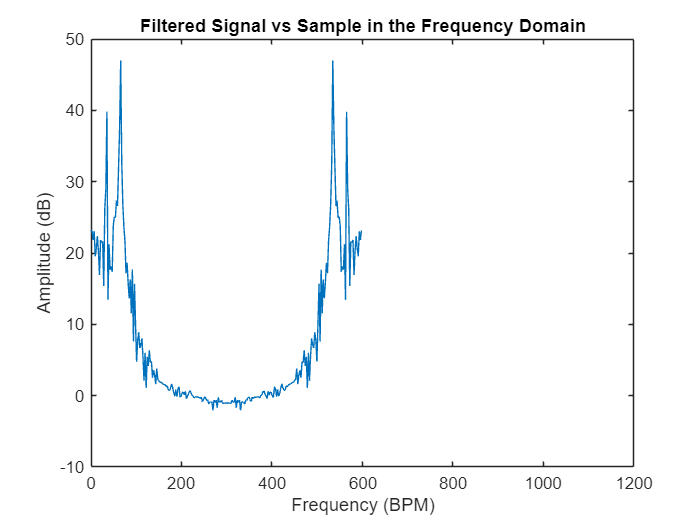

freqResponseFilter = fft(filteredSignal);  % find frequency response by taking FFT of signal values
freqResponseFilterMag = 20*log10(abs(freqResponseFilter));  % find the absolute magnitude of the frequency response in dB

figure
grid 'on'
plot(BPM, freqResponseFilterMag)
xlim([0 nyquistBPM])
xlabel("Frequency (BPM)")
ylabel("Amplitude (dB)")
title("Filtered Signal vs Sample in the Frequency Domain")

## Problem 3 --  Properties of the DFT (25 points)

#### A) (5 Pts)  An input sequence consists of 120 time domain samples and the sample rate is 48 kHz, what is the frequency resolution of the DFT of the input sequence?  Compute your answer below.

clear  % clear workspace
N = 120;
fs = 48 * 10^3;
fres = fs / N

fres = 400

#### B) (5 Pts) How can you improve the resolution of the above FFT to better than 36 Hz.  Be sure to use an FFT length that is a power of 2.  Compute your answer below.

% find new amount of samples
fresDesired = 36;
numSamples = fs / fresDesired;

% find next highest power of 2
e = ceil(log2(numSamples));
newSamples = 2^e;  % new sample rate

% compute new frequency resolution
fresNew = fs / newSamples

fresNew = 23.4375

#### C) (5 Pts) If the input values to the DFT are multiplied by 8.5 what happens to the output values of the DFT?  Type your answer below.

The output values from the DFT will also be multiplied by 8.5, as the DFT exhibits homogeneity as a linear system.

#### D) (10 Pts) If the DFT of an input sequence a[n]  is A[k] and the DFT of a second input sequence b[n] is B[k] what is the DFT of 6*a[n]+3*b[n] in terms of A[k] and B[k]?  Type your answer below.

#### A diagram of the system is shown below:

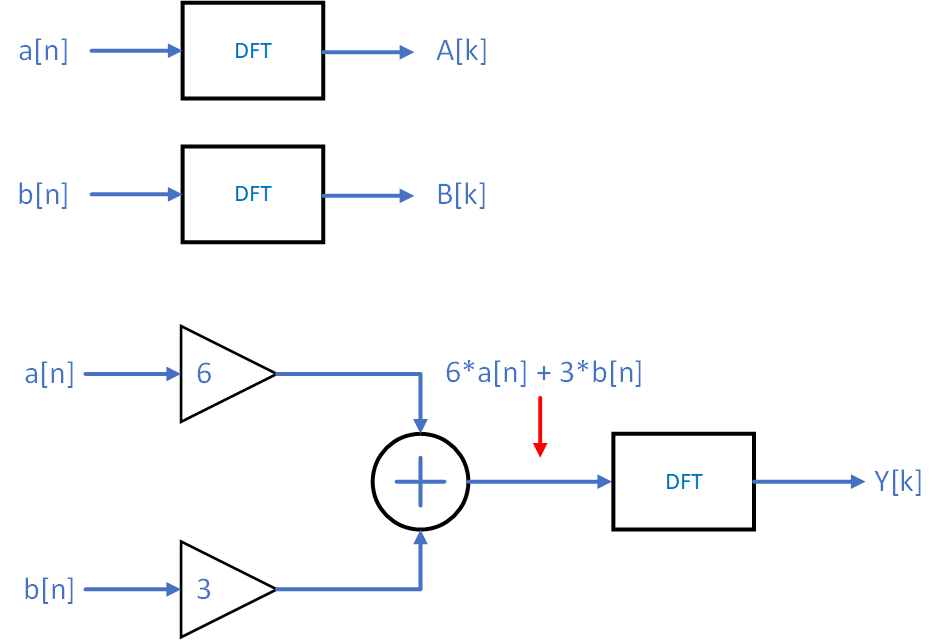

The DFT of the input signals is 6*A[k] + 3*B[k]. This is because of the property of additivity, which means DFT(6*a[k] + 3*b[k]) is equal to DFT(6*a[k]) + DFT(3*b[k]). This is also because of the product of homogeneity, which means DFT(6*a[k]) is 6*A[k] and DFT(3*b[k]) is 3*B[k].

## Problem 4 -- Convolution in the frequency domain (25 points)

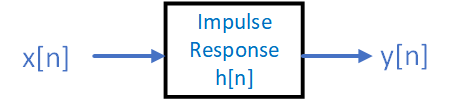

#### An input sequence is applied to a filter that has an impulse response of h[n] that is shown below

#### h = [ 0.0176    0.0480    0.1223    0.1976    0.2290    0.1976    0.1223    0.0480    0.0176 ]' ;

#### The file Exam_02_2241_Problem_04.mat' contains a variable "outData" that is to be used as the input to the filter.  There are two columns in the variable "outData".  The first column is the sample number and the second column is the value of the signal. 

#### A) (3 Pts)  Load the file.  What is the length of the signal?  Find the sequence length (using MATLAB code) and either type or print your answer.

clear
load("Exam_02_2241_Problem_04.mat")

length(outData(:,2))

ans = 248

#### B) (2 pts)  Create a variable h that is the impulse response of the filter (Hint: Copy this from the problem statement above).  What is the length of the impulse response?

h = [0.0176 0.0480 0.1223 0.1976 0.2290 0.1976 0.1223 0.0480 0.0176];
length(h)

ans = 9

#### C) (5 Pts) What will be the length of the output y[n]?  y[n] is the input x[n] convolved with the impulse response h[n]?  (Type your answer below)

#### The length of the ouput y[n] is equal to the length of the input x[n] plus the length of the impulse response h[n] minus 1, or 248 + 9 - 1, which is equal to 256 samples.

#### D) (5 Pts) When convolving the two signals in the frequency domain, to what length do the FFT's need to be padded to?  (Type your answer below)

#### The FFTs would need to be padded to 256 samples each.

#### E) (10 Pts) Convolve the two signals in the frequency domain using MATLAB (do not use the MATLAB 'conv' function).  Be sure when entering the impulse response in MATLAB that you enter it as a column vector.  The input signal (column 2 of the variable signal from the MATLAB file) is already a column vector. Also recall that to do point by point multiplication in MATLAB  use the dot operator before the multiplication operator (i.e.   .* ).  Plot a graph of the input signal and the output of the filter y[n] on the same graph.  Add appropriate titles and axes labels.

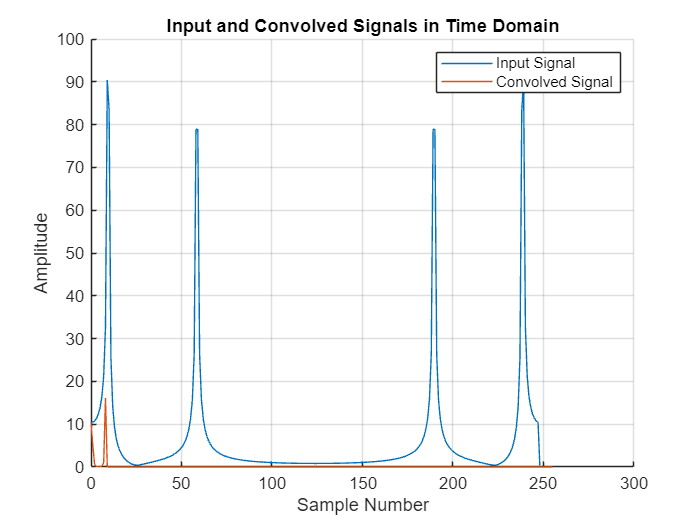

x = 0:255;  % create sample numbers of proper size

xn = outData(:,2);
xnfreq = abs(fft(xn));  % convert input to frequency domain
xnfreqPadded = [xnfreq; zeros([8 1])];  % pad input fft

hn = [0.0176; 0.0480; 0.1223; 0.1976; 0.2290; 0.1976; 0.1223; 0.0480; 0.0176];
hnfreq = abs(fft(hn));  % convert impulse response to frequency domain
hnfreqPadded = [hnfreq; zeros([247 1])];  % pad impulse fft

conv = xnfreqPadded .* hnfreqPadded;  % perform frequency domain convolution

figure
hold 'on'
grid 'on'
plot(x, xnfreqPadded)
plot(x, conv)
xlabel("Sample Number")
ylabel("Amplitude")
title("Input and Convolved Signals in Time Domain")
legend("Input Signal", "Convolved Signal")